T = 8e-3; % 8 ms
% Leitura da tabela
OutTab = readtable("Saidas.csv")

OutTab = 381×4 table
      Tempo       Entrada    Erro    Saida
    __________    _______    ____    _____

           544       105     200        0 
          8248     107.4     200        0 
         15856    109.81     200        0 
         23524    112.21     200        1 
         31212    114.56     199       12 
         38948    116.34     188       30 
         46684     117.6     170       58 
         54416     118.1     142       88 
         62144    118.14     112      119 
         69936    117.77      81      149 
         77672    117.09      51      174 
         85400    116.32      26      195 
         93136    115.47       5      213 
    1.0082e+05    114.53     -13      231 
    1.0861e+05    113.38     -31      247 
    1.1641e+05    112.12     -47      268 


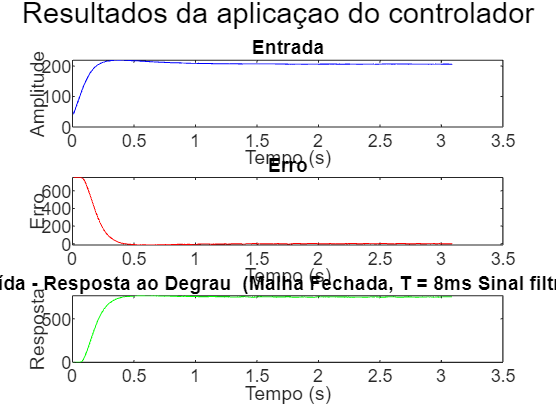


% Vetor de tempo
tout = 1:length(OutTab.Tempo);
tout = tout * T;

% Criação da figura com subplots
figure;

% Subplot 1 - Entrada
subplot(3,1,1);
plot(tout, OutTab.Entrada, 'b');
title('Entrada');
xlabel('Tempo (s)');
ylabel('Amplitude');

% Subplot 2 - Erro
subplot(3,1,2);
plot(tout, OutTab.Erro, 'r');
title('Erro');
xlabel('Tempo (s)');
ylabel('Erro');

% Subplot 3 - Saída
subplot(3,1,3);
plot(tout, OutTab.Saida, 'g');
title('Saída - Resposta ao Degrau (Malha Fechada, T = 8ms)');
xlabel('Tempo (s)');
ylabel('Resposta');
title('Saída - Resposta ao Degrau  (Malha Fechada, T = 8ms Sinal filtrado)');
xlabel('Tempo (s)');
ylabel('Resposta');

% Ajusta o layout
sgtitle('Resultados da aplicaçao do controlador');
hold off;

info = stepinfo(OutTab.Saida, tout);

% Tempo de acomodação a 2%
Ts = info.SettlingTime

Ts = 1.2101

Tr = info.RiseTime

Tr = 0.1770

Tp= info.PeakTime

Tp = 0.6320

UP= info.Overshoot

UP = 2.5172